clc;
clear all;
close all;

***Pregunta 2:***

Tenemos la siguiente función de transferencia para un filtro pasa bajos:

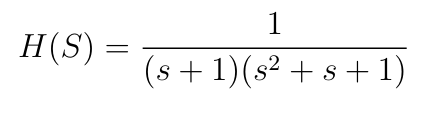

***Inciso a)***

Grafique la respuesta en frecuencia del filtro analógico y estime los valores de amplitud y frecuencia de corte.

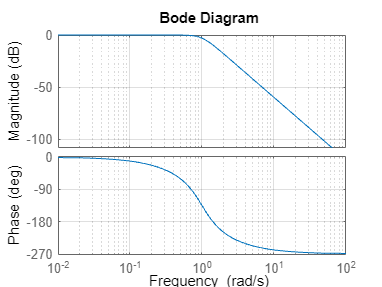

% Definimos la función de transferencia H(s) 
H = tf(1, conv([1, 1], [1, 1, 1]));

% Graficamos la respuesta en frecuencia
figure(1);
bode(H);
grid on;

Podemos estimar los valores de la frecuencia de corte y su amplitud observando el diagrama de bode y después comprobando con comando bandwith el cual nos dirá cual es el ancho de banda o frecuencia de corte del filtro.

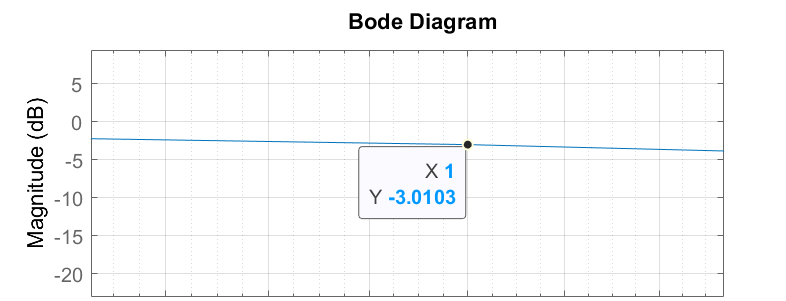

De la imagen anterior sabemos que la frecuencia de corte ocurre cuando nuestra magnitud de nuestra gráfica cae -3dB , es decir nuestra frecuencia de corte tendria que ser un valor muy cercano a 1 rad/s.

Por otro lado la amplitud máxima que tenemos es la de 0db ,es decir una magnitud igual a 1 que dejará pasar todas nuestras frecuencias hasta la respestiva frecuencia de corte.

%Podemos estimar los valores de la frecuencia de corte y su amplitud máxima
Frec_corte = bandwidth(H);
ganancia_pico=getPeakGain(H)

ganancia_pico = 1

% Mostrar los valores estimados
fprintf('La ganancia de pico es: %f\n', ganancia_pico);

La ganancia de pico es: 1.000000


fprintf('La frecuencia de corte es: %f rad/s\n', Frec_corte);

La frecuencia de corte es: 0.999209 rad/s


Con lo anterior comprobamos los valores de frecuencia de corte y la ganancia pico que tenemos con nuestra función de transferencia del filtro.

***Inciso b)***

Aplicando el método de invarianza del impulso, se desea diseñar un filtro digital en función del filtro analógico H(s). Para ello determine la frecuencia de muestreo adecuada para que la frecuencia de corte del filtro digital sea 0,4π. Grafique la respuesta en frecuencia en magnitud y fase del filtro digital diseñado.

De la teoria sabemos que : f_norm=fc_deseada/fs

%fs=fc_deseada/f_norm
fc_deseada=0.4*pi

fc_deseada = 1.2566

f_norm=Frec_corte/(2*pi)

f_norm = 0.1590

fs=fc_deseada/f_norm

fs = 7.9019

ts=1/fs

ts = 0.1266


%Hallamos la función de transferencia en el plano z discretizando la que ya
%tenemos
H_z=c2d(H,ts,'impulse')

H_z =
 
  0.0009305 z^2 + 0.0008553 z - 2.403e-18
  ---------------------------------------
    z^3 - 2.747 z^2 + 2.525 z - 0.7764
 
Sample time: 0.12655 seconds
Discrete-time transfer function.
Model Properties


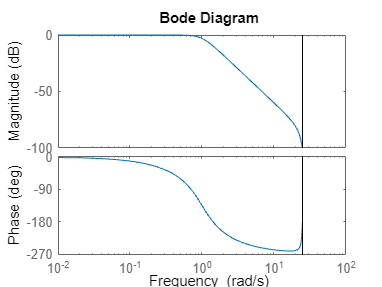

%Hallamos el diagrama de bode de la función de transferencia 
bode(H_z)

***Inciso c)***

A plicando el método de transformación bilineal, se desea diseñar un filtro digital en función del filtro analógico H(s). Para ello determine el valor que debe tomar el parámetro de transformación α para que la frecuencia de corte del filtro digital sea 0,4π. Grafique la respuesta en frecuencia en magnitud y fase del filtro digital diseñado.

Para la transformación bilineal un parámetro adecuado para el alfa =2/T

%Definimos el valor de alfa
alfa=2/ts

alfa = 15.8039

%Hallamos la nueva función de transferencia con el metodo de la
%transformada bilineal
Hz_bl=c2d(H,ts,'tustin')

Hz_bl =
 
  0.0002232 z^3 + 0.0006697 z^2 + 0.0006697 z + 0.0002232
  -------------------------------------------------------
            z^3 - 2.747 z^2 + 2.526 z - 0.7765
 
Sample time: 0.12655 seconds
Discrete-time transfer function.
Model Properties


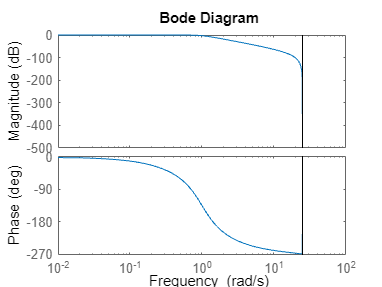

bode(Hz_bl)

***Inciso d)***

Si bien nuestros resultados pueden ser parecidos en cuanto a su respuesta en frecuencia existen ciertos puntos a tener en cuenta para cada uno de los métodos, para empezar el método de invariaza del impulso al tener una respuesta impusional resultado de haber muestreado la respuesta al impulso del filtro anlógico , podriamos tener el caso de un posible Alising debido a que el muestreo que realiza es de muchos a uno , por el contrario esto no sucede con el metodo de la transformación bilineal ya que cada punto de nuestro semiplano s se transforma en un punto al interior del citculo unitario del plano z, esto nos asegura la estabilidad del filtro.